# ME 140 Exam 3 - Caleb Bahne

## Problem 21

A = [-3 5; 110 -302];
% help eig
[V,D] = eig(A)

V =     0.9392   -0.0166
    0.3434    0.9999


D =    -1.1717         0
         0 -303.8283



% polynomial method
p = poly(A) % char polynomial coeffs

p =     1.0000  305.0000  356.0000


% help poly

 poly Convert roots to polynomial.
    poly(A), when A is an N by N matrix, is a row vector with
    N+1 elements which are the coefficients of the
    characteristic polynomial, det(lambda*eye(size(A)) - A).
 
    poly(V), when V is a vector, is a vector whose elements are
    the coefficients of the polynomial whose roots are the
    elements of V. For vectors, ROOTS and poly are inverse
    functions of each other, up to ordering, scaling, and
    roundoff error.
 
    Examples:
 
    roots(poly(1:20)) generates Wilkinson's famous example.
 
    Class support for inputs A,V:
       float: double, single
 
    See also roots, conv, residue, polyval.

    Documentation for poly
    

d = roots(p) % eigenvals

d =  -303.8283
   -1.1717


## Problem 22

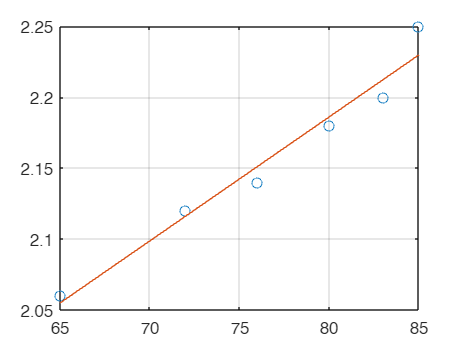

a =     0.0087    1.4864


r2 = 0.9656

W = [65 72 76 80 83 85];
A = [2.06 2.12 2.14 2.18 2.20 2.25];

[a r2] = linregr(W,A)

% help linregr
% log10(A) = log10(alph) + beta*log10(W)
[a_pl, r2_pl] = linregr(log10(W), log10(A))

a_pl =     0.3025   -0.2359


r2_pl = 0.9608

alpha = 10^(a_pl(2))

alpha = 0.5809

beta  = a_pl(1)

beta = 0.3025

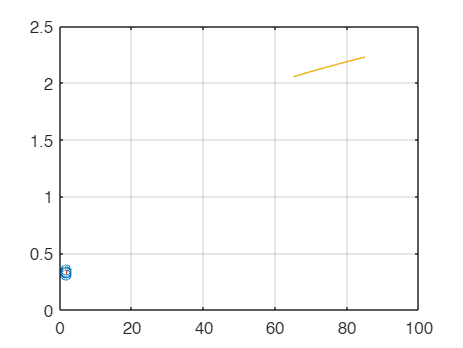


% check results
hold on;
fplot(@(x) alpha*x^beta, [65 85]); hold off;


% nonlinear method doublecheck
nlm = fitnlm(W,A, @(b,W) b(1)*W.^b(2), [1 1])

nlm = Nonlinear regression model:
    y ~ b1*W^b2

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1    0.57562     0.079288      7.26     0.0019116
    b2    0.30461     0.031712    9.6053    0.00065668


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.015
R-Squared: 0.959,  Adjusted R-Squared 0.949
F-statistic vs. zero model: 6.18e+04, p-value = 1.05e-09

% seems consistent with transform and the Excel plot below

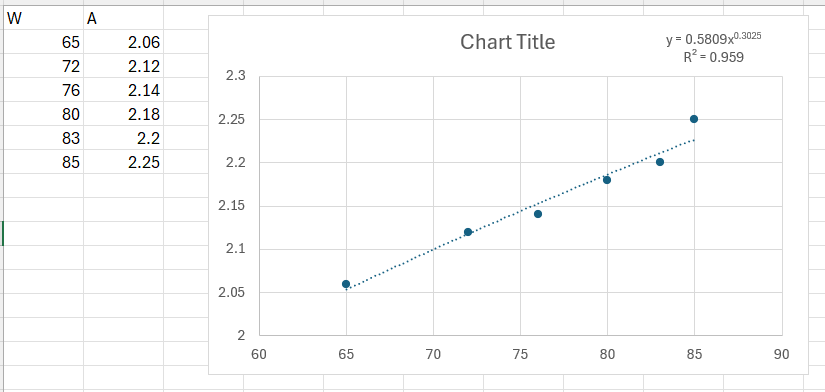

## Problem 23

x = [1 2 3 4 5 6 7];
y = [3.5 1.6 1.3 0.85 0.76 1.4 0.54];

% Newton interp poly
% help Newtint
xx = 1.7;
yint = Newtint(x,y,xx)

yint = 1.8225


% Lagrange (no exclusion of the last point)
help Lagrange

  Lagrange: Lagrange interpolating polynomial
  yint = Lagrange(x,y,xx): Uses an (n order
    Lagrange interpolating polynomial based on n data points
    to determine a value of the dependent variable (yint) at
    a given value of the independent variable, xx.
  input:
    x = independent variable
    y = dependent variable
    xx = value of independent variable at which the
        interpolation is calculated
  output:
    yint = interpolated value of dependent variable



xx = 1.5;
yint_L = Lagrange(x,y,xx)

yint_L = 2.0879

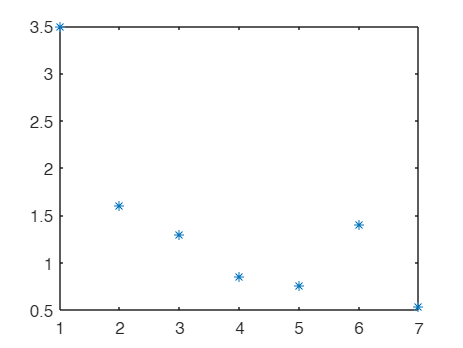


% plot to evaluate the last value
plot(x,y,'*')


% Lagrange (exclude last point)
x1 = [1 2 3 4 5];
y1 = [3.5 1.6 1.3 0.85 0.76];
yint_L1 = Lagrange(x1,y1,xx)

yint_L1 = 2.1523


% Relative error
re = abs(yint_L1-yint_L)/yint_L1

re = 0.0299


% polyint
polyint(x,y,xx) % similar to the Lagrange way

ans = 2.0879

## Problem 24

% Romberg integration
f = @(x) x.^2 + 4*x.^(-2) - 4;
a = 1; b = 4; es = 1;
% help romberg
[q,ea,iter] = romberg(f,a,b,es)

q = 12.0448

ea = 0.1869

iter = 2


% integral
q1 = integral(f,a,b)

q1 = 12